# Method#3 Random Midpoint

## 隨機中點法

前置作業

r = 1;
syms x y
t = [0;1];
R = [cos(2*pi/3) -sin(2*pi/3); sin(2*pi/3) cos(2*pi/3)];
t = [t R*t R^2*t t]';
a = norm(t(1,:)-t(2,:));

挑點

n = 3000;
r_radius = sqrt(rand(n,1))*r;
r_angle = rand(n,1)*2*pi;
rx = r_radius.*cos(r_angle);
ry = r_radius.*sin(r_angle);

(1/2*b)^2 = r^2 - rx^2 - ry^2

B = sqrt(1 - r_radius.^2)*2;
result = B>a;

隨機中點法動畫展示

v = [-ry rx]./r_radius;
p1 = [rx ry] + 1/2*B.*v;
p2 = [rx ry] - 1/2*B.*v;
for i = 1:length(rx)
    fimplicit(x^2+y^2 == r^2, [-2 2, -2 2],'b');
    hold on;
    plot(t(:,1),t(:,2),'Color','#D95319');
    fimplicit(x^2+y^2 == (r/2)^2,'b');
    chord = [p1(i,:);p2(i,:)];
    plot(rx(i),ry(i),'o','MarkerFaceColor','r');
    if result(i)
        plot(chord(:,1),chord(:,2),'g-');
    else
        plot(chord(:,1),chord(:,2),'r-');
    end
    axis equal;
    hold off;
    pause(0.01);
end

計算機率

sum(result)/length(result)

ans = 0.2580

弦分布

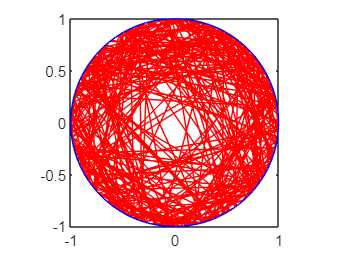

clf;
N = 300;
r_radius = sqrt(rand(N,1))*r;
r_angle = rand(N,1)*2*pi;
rx = r_radius.*cos(r_angle);
ry = r_radius.*sin(r_angle);
B = sqrt(1 - r_radius.^2)*2;
v = [-ry rx]./r_radius;
p1 = [rx ry] + 1/2*B.*v;
p2 = [rx ry] - 1/2*B.*v;
for i = 1:length(rx)
    fimplicit(x^2+y^2 == r^2, [-1 1, -1 1],'b');
    hold on;
    chord = [p1(i,:);p2(i,:)];
    plot(chord(:,1),chord(:,2),'r-');
    axis equal;
end
hold off;

割線中點分布

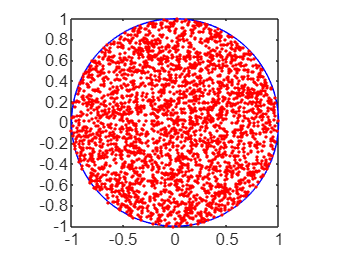

clf;
N = 3000;
theta = 2*pi*rand(N,1);
rr = sqrt(rand(N,1));
rx = rr.*cos(theta);
ry = rr.*sin(theta);
fimplicit(x^2+y^2 == r^2, [-1 1 -1 1], 'b');
hold on;
axis equal;
plot(rx,ry,'r.');
hold off;